Horizontal Shear

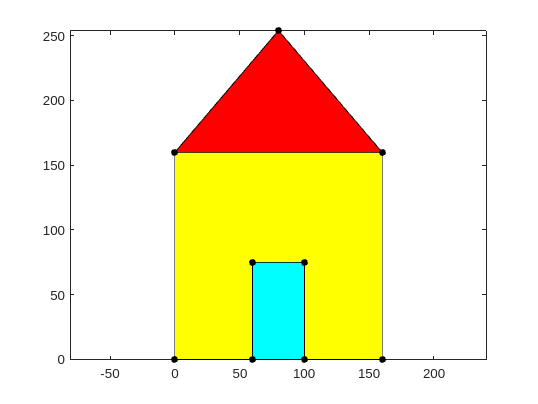

clf;

X1=[0 160 160 0]; Y1=[0 0 160 160]; P1=[X1;Y1]; % yellow
X2=[0 160 80]; Y2=[160 160 254]; P2=[X2;Y2]; % red
X3=[60 100 100 60]; Y3=[ 0 0 75 75]; P3=[X3;Y3]; % cyan
patch(X1,Y1,'y'); axis equal; hold on; box on; patch(X2,Y2,'r'); patch(X3,Y3,'c')
P=[P1 P2 P3]; plot(P(1,:),P(2,:),'.k','MarkerSize',15)

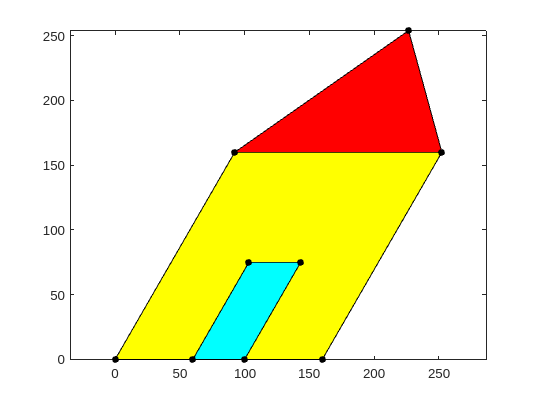


clf;

th=pi/6; r=tan(th); A=[1 r;0 1]; Q1=A*P1; Q2=A*P2; Q3=A*P3; Q=[Q1 Q2 Q3];
patch(Q1(1,:),Q1(2,:),'y'); axis equal; hold on; box on
patch(Q2(1,:),Q2(2,:),'r'); patch(Q3(1,:),Q3(2,:),'c')
plot(Q(1,:),Q(2,:),'.k','MarkerSize',15)

clf;

Translation in R^2

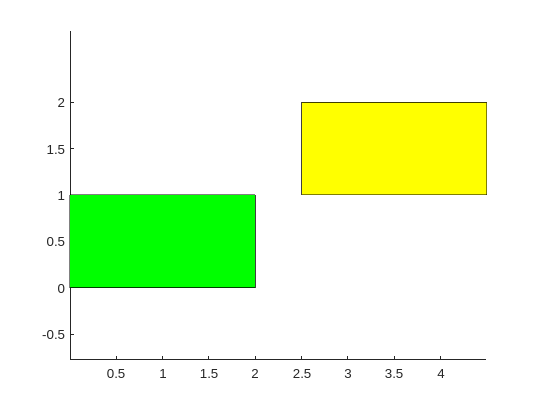

b=[2.5 1]'; A=[eye(2) b;0 0 1];
X=[0 2 2 0];Y=[0 0 1 1]; P=[X;Y;ones(size(X))];
patch(P(1,:),P(2,:),P(3,:),'g'); axis('equal'); hold on
Q=A*P;
patch(Q(1,:),Q(2,:),Q(3,:),'y')

Rotation around axis

clf;
vert=[0 0 0; % 1
2 0 0; % 2
2 1 0; % 3
0 1 0; % 4
0 0 1; % 5
2 0 1; % 6
2 1 1; % 7
0 1 1] % 8

vert =      0     0     0
     2     0     0
     2     1     0
     0     1     0
     0     0     1
     2     0     1
     2     1     1
     0     1     1


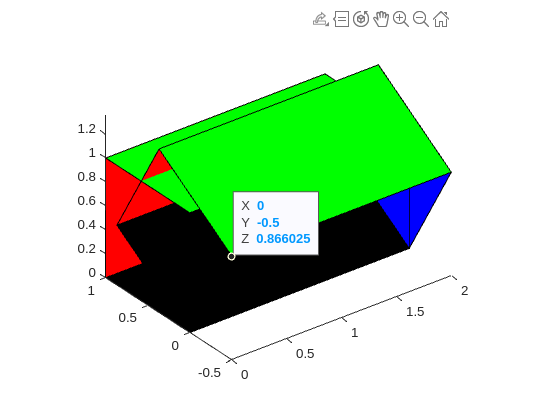


face=[1 2 3 4; % 1
3 7 8 4; % 2
2 3 7 6; % 3
5 6 7 8]; % 4

col=[0 0 0; % 1
1 0 0; % 2
0 0 1; % 3
0 1 0]; % 4

alpha=pi/6; A=blkdiag(1,[cos(alpha) -sin(alpha);sin(alpha) cos(alpha)]);
B=A*vert';
patch('Faces',face,'Vertices',B','FaceVertexCData',col,'FaceColor','flat')
view(3); axis equal; axis tight; hold on
patch('Faces',face,'Vertices',vert, 'FaceVertexCData',col,'FaceColor','flat')


clf;

Translation by (1,1,2)^T

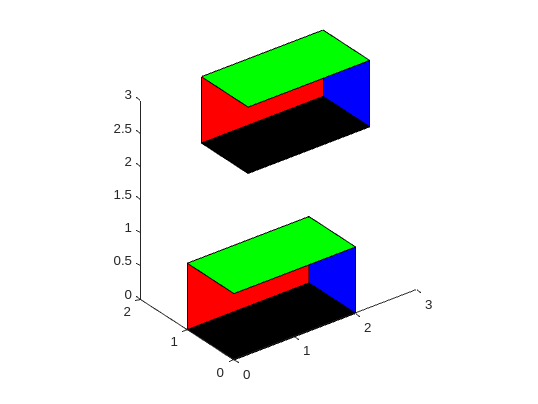

clf;
b=[1;1;2]; B=vert' + b;
patch('Faces',face,'Vertices',B','FaceVertexCData',col,'FaceColor','flat')
view(3); axis equal; axis tight; hold on
patch('Faces',face,'Vertices',vert,'FaceVertexCData',col,'FaceColor','flat')